## What direction does the mouse turn the wheel? 

Let's assign a turning direction for each trial. 

data = readtable('data/matlab_table/data_active_pos_fb_response_only.xml');
%data = readtable('data/matlab_table/data_active_pos_fb.xml');


An indicator of turning direction maybe the average turning velocity. 

The direction is estimated by the sign of the average (<0 -> left turn , >0 -> right turn)

mean_turn_vels = mean( data.wheel_speed, 2, 'omitmissing');
% equivalent 
mean_turn_vels = mean( data.wheel_speed', 'omitmissing')';

data.mean_wheel = mean_turn_vels;


plot first 10 trials with mean velocity greater than 0 

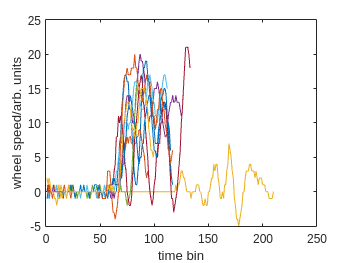

dd= data(data.mean_wheel>0, 'wheel_speed');
plot(dd{1:10, 'wheel_speed'}')
xlabel('time bin')
ylabel('wheel speed/arb. units')

Looks like average velocity could be reasonable indicator. Now plot all trials

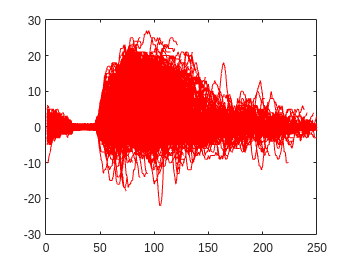

plot(data{data.mean_wheel>0, 'wheel_speed'}', 'Color','r')

Overplotting is an issue. Plot instead a datashader type figure 

data_ = data(data.mean_wheel>0,:);
yy =flip([min(data_.wheel_speed,[],'all'):1:max(data_.wheel_speed,[],'all')]');
ss =size(data_.wheel_speed);
res =zeros([length(yy),ss(2)]);

for i=1:ss(2)
    [n, edges]= histcounts(data_.wheel_speed(:,i),[min(data_.wheel_speed,[],'all'):max(data_.wheel_speed,[],'all')+1]);% REMOVE HARDCODING
    res(:,i) = n';
end
res = flip(res);

Plot as image (better than heatmap as colorscale can be set to logarithmic)

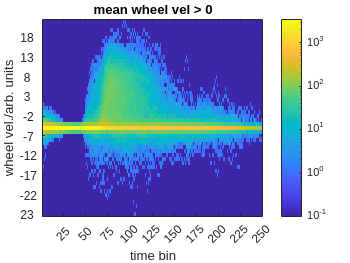

im=image(res,'CDataMapping','scaled');
colorbar
set(gca,'ColorScale','log')

title('mean wheel vel > 0')

% add axis tick labels
set(gca, 'XTick',[0:25:250], 'XTickLabel',[0:25:250])    
set(gca, 'YTick',[0:5:50], 'YTickLabel',flip([min(data_.wheel_speed,[],'all'):5:max(data_.wheel_speed,[],'all')]))    
xlabel('time bin')
ylabel('wheel vel./arb. units')

Sanity check - make same plot for mean wheel vel <0 

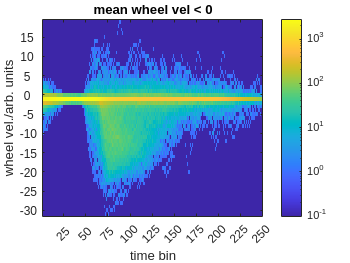

data_ = data(data.mean_wheel<0,:);
yy =flip([min(data_.wheel_speed,[],'all'):1:max(data_.wheel_speed,[],'all')]');
ss =size(data_.wheel_speed);
res =zeros([length(yy),ss(2)]);

for i=1:ss(2)
    [n, edges]= histcounts(data_.wheel_speed(:,i),[min(data_.wheel_speed,[],'all'):max(data_.wheel_speed,[],'all')+1]);% REMOVE HARDCODING
    res(:,i) = n';
end
res = flip(res);

im=image(res,'CDataMapping','scaled');
colorbar
set(gca,'ColorScale','log')

title('mean wheel vel < 0')

% add axis tick labels
set(gca, 'XTick',[0:25:250], 'XTickLabel',[0:25:250])    
set(gca, 'YTick',[0:5:50], 'YTickLabel',flip([min(data_.wheel_speed,[],'all'):5:max(data_.wheel_speed,[],'all')]))    
xlabel('time bin')
ylabel('wheel vel./arb. units')

Ok, the average wheel velocity looks like a decent indicator of turning direction. 

Lets improve by integrating velocity with time to calculate position.

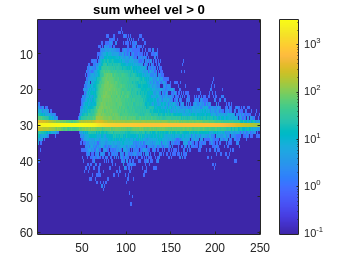

data.sum_wheel = sum(data.wheel_speed,2,'omitmissing');

data_ = data(data.sum_wheel>0,:);
yy =flip([-30:29]'); % REMOVE HARDCODING

ss =size(data_.wheel_speed);
res =zeros([length(yy),ss(2)]);
for i=1:ss(2)
    [n, edges]= histcounts(data_.wheel_speed(:,i),[-30:30]);% REMOVE HARDCODING
    res(:,i) = n';
end
res = flip(res);

im=image(res,'CDataMapping','scaled');
colorbar
set(gca,'ColorScale','log')

title('sum wheel vel > 0')

% add axis labels

Because the time bin widths are uniform,  integrating and taking the mean give the same result!

## Histograms

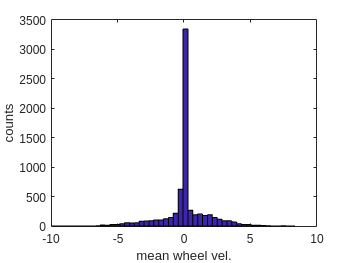

hist(data.mean_wheel, 50)

xlabel('mean wheel vel.')
ylabel('counts')